Acquisition de l'image

chemin_woman = '/Users/homefolder/Desktop/BE2-Image_filtering_frequency2324/Fig_woman.tif';
chemin_barre = '/Users/homefolder/Desktop/BE2-Image_filtering_frequency2324/Fig_Barre500.tif';


A. 2.1 Affichage de la magnitude et de la phase.

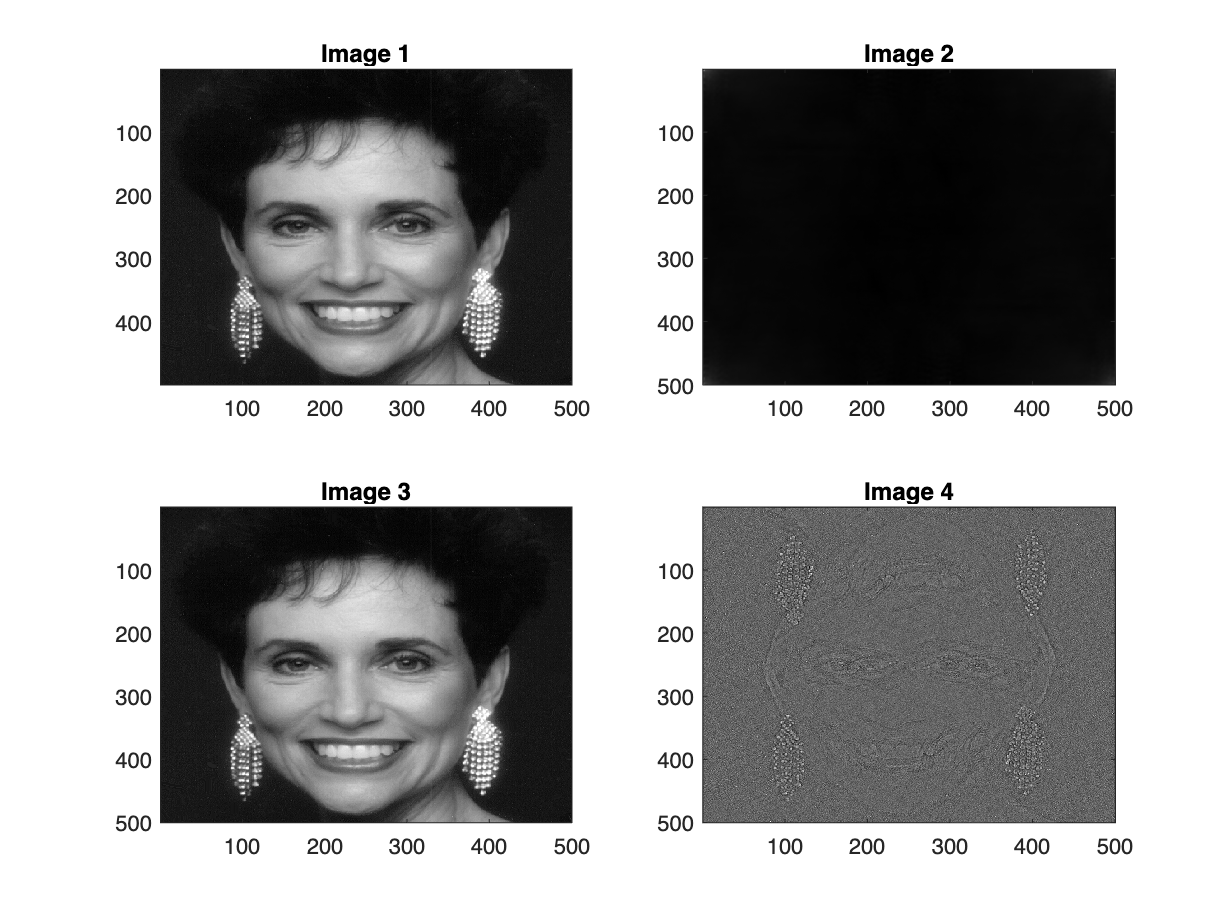

im_woman = imread(chemin_woman);
[woman_mag, woman_phase] = make_ph_mag(chemin_woman);

afficher_images_grid(im_woman, woman_mag, im_woman, woman_phase)

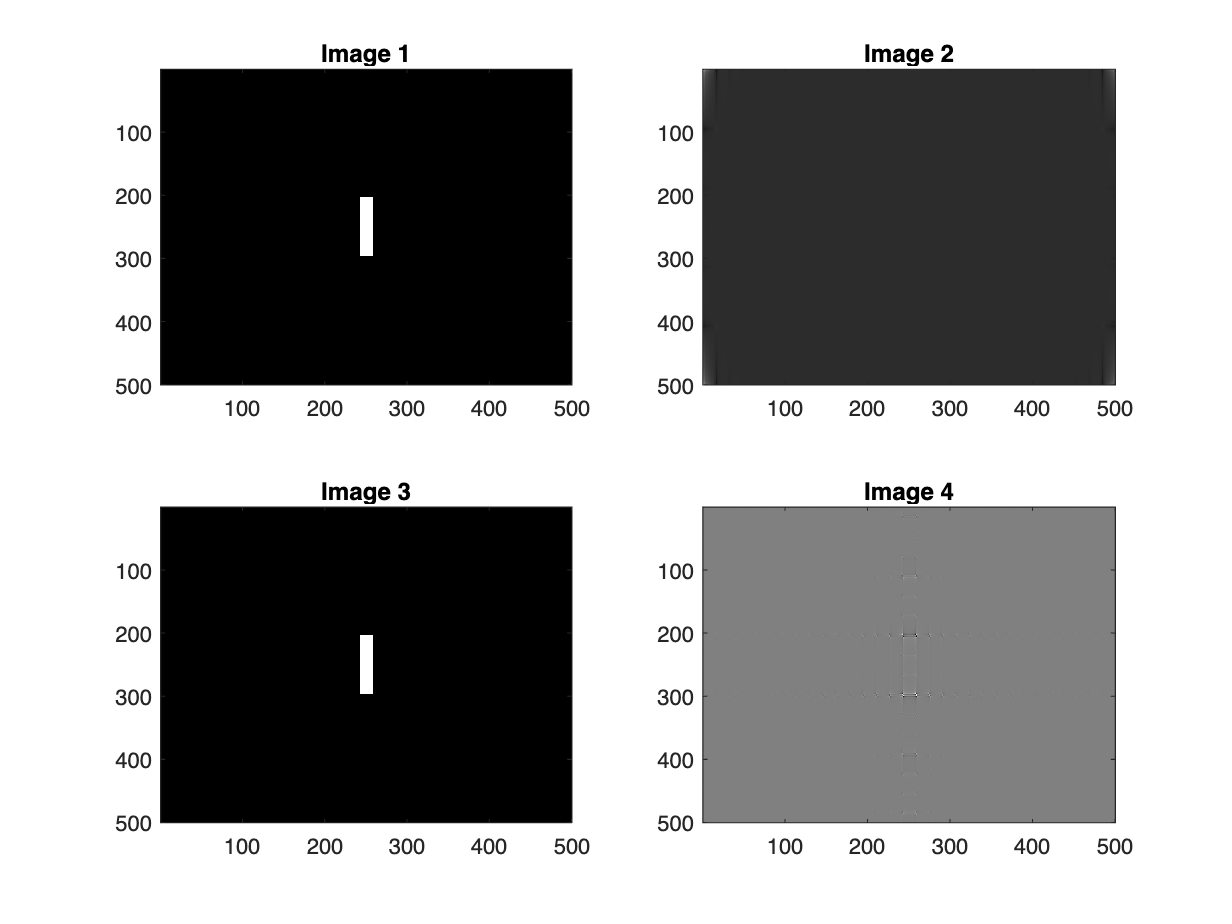

im_barre = imread(chemin_barre);
[barre_mag, barre_phase] = make_ph_mag(chemin_barre);

afficher_images_grid(im_barre, barre_mag, im_barre, barre_phase)

A.2.2 Affiche du croisement entre la phase et la magnitude de chaque image

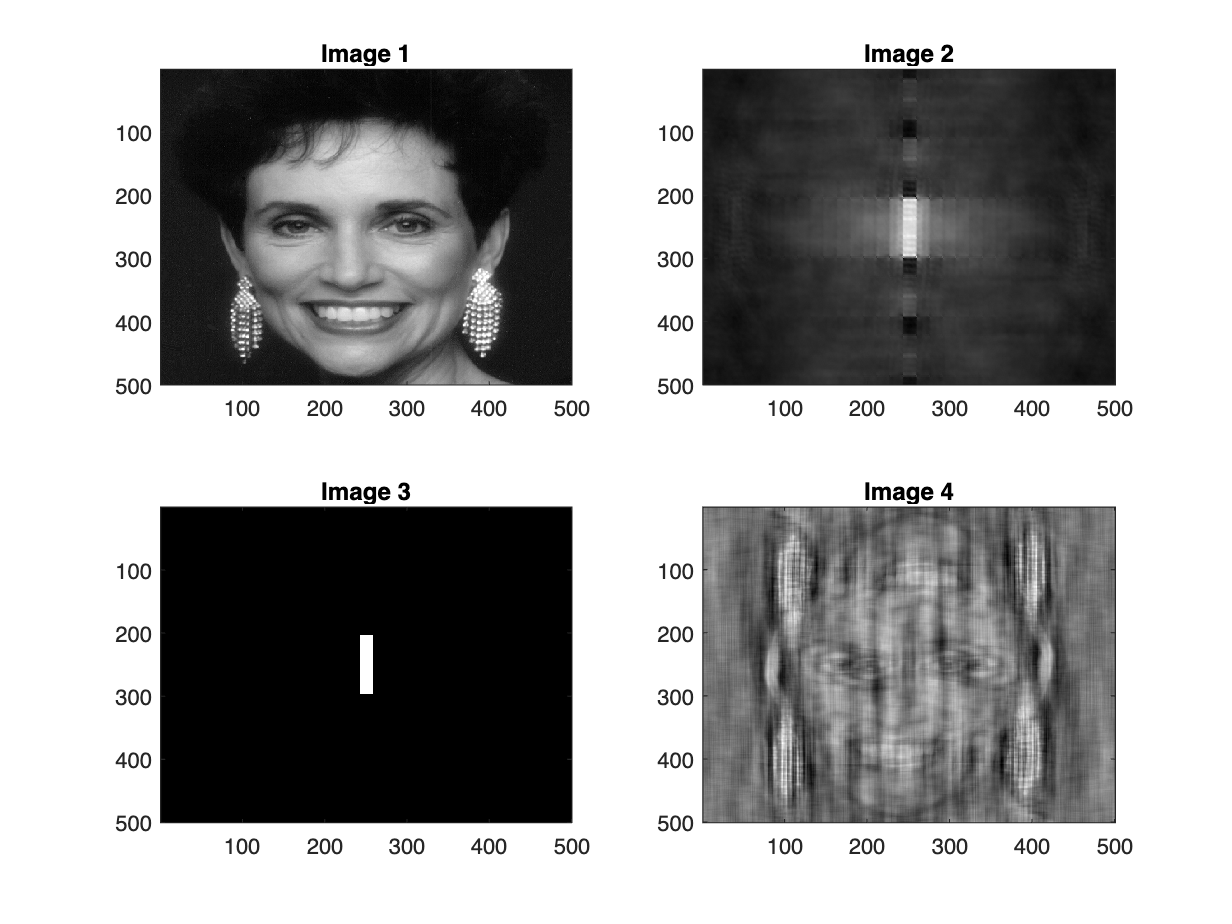

[barre_cross] = cross_ph_mag(im_woman, im_barre);
[woman_cross] = cross_ph_mag(im_barre, im_woman);

afficher_images_grid(im_woman, woman_cross, im_barre, barre_cross)

subplot(2,2,4)
xlim([1 501])
ylim([1 501])

Fonctions utilisées dans ce code.

function [im_mag, im_phase] = make_ph_mag(chemin) %Création des images de magnitude et de phase
    %Acquisition et fft2 de l'image
    im = imread(chemin);
    im_fft2 = fft2(im);

    %Génération de l'image magnitude 
    im_fft2_mag = abs(im_fft2);
    im_mag = ifft2(im_fft2_mag);
    
    %Génération de l'image phase
    im_fft2_phase = real(exp(1i*angle(im_fft2)));
    im_phase = ifft2(im_fft2_phase);
end

%Affichage de quatre images dans une grid 4x4
function afficher_images_grid(img1, img2, img3, img4)
    figure;

    subplot(2, 2, 1);
    imagesc(img1);
    colormap gray;
    title('Image 1');

    subplot(2, 2, 2);
    imagesc(img2);
    colormap gray;
    title('Image 2');

    subplot(2, 2, 3);
    imagesc(img3);
    colormap gray;
    title('Image 3');

    subplot(2, 2, 4);
    imagesc(img4);
    colormap gray;
    title('Image 4');

    hold off;
end

%Création des croisements d'images
function [image_cross] = cross_ph_mag(im1, im2)
    im1_fft2_phase = angle(fft2(im1));
    im1_phase = real(exp(1i*im1_fft2_phase));
    
    im2_mag = abs(fft2(im2));
    image_cross = ifft2(im1_phase.*im2_mag);
    
end